# **神经网络反向传播主程序**

%% Initialization
clear ; close all; clc

%% Setup the parameters you will use for this exercise
input_layer_size  = 400;  % 20x20 Input Images of Digits
hidden_layer_size = 25;   % 25 hidden units
num_labels = 10;          % 10 labels, from 1 to 10   
                          % (note that we have mapped "0" to label 10)

times = 30;
step = 1;
times_start = 10;
times_end= times_start + step*times;
acc_times = zeros(1,times+1);
for i = 0:times
fprintf(['------------------------第 %d 轮--------------------------\n'],i);
%% =========== Part 1: 加载和可视化数据 =============
%  We start the exercise by first loading and visualizing the dataset. 
%  You will be working with a dataset that contains handwritten digits.
% Load Training Data
load('ex1data.mat');
m = size(X, 1);

% Randomly select 100 data points to display
sel = randperm(size(X, 1));
sel = sel(1:100);
% displayData(X(sel, :));
fprintf('数据已经加载完成并可视化。\n');

%% ================ Part 2: 加载参数 ================
% In this part of the exercise, we load some pre-initialized neural network parameters.
% Load the weights into variables Theta1 and Theta2
load('ex1weights.mat');

% Unroll parameters 
nn_params = [Theta1(:) ; Theta2(:)];
fprintf('参数已经加载完成。\n');

%% ================ Part 3: 计算成本（前向） ================
%  To the neural network, you should first start by implementing the feedforward part of the neural network that returns the cost only.
%  You should complete the code in nnCostFunction.m to return cost. 
%  After implementing the feedforward to compute the cost, 
%  you can verify that your implementation is correct by verifying that you get the same cost as us for the fixed debugging parameters.
%
%  We suggest implementing the feedforward cost *without* regularizationfirst so that it will be easier for you to debug.
%  Later, in part 4, you will get to implement the regularized cost.

% Weight regularization parameter (we set this to 0 here).
lambda = 0;
J = nnCostFunction(nn_params, input_layer_size, hidden_layer_size, ...
                   num_labels, X, y, lambda);

fprintf(['Cost at parameters (loaded from ex1weights): %f '...
         '\n(this value should be about 0.288401 )\n'], J);
fprintf('\n第三部分完成\n');

%% =============== Part 4: 实现正则化 ===============
%  Once your cost function implementation is correct, 
%  you should now continue to implement the regularization with the cost.

% Weight regularization parameter (we set this to 1 here).
lambda = 1;
J = nnCostFunction(nn_params, input_layer_size, hidden_layer_size, ...
                   num_labels, X, y, lambda);

fprintf(['Cost at parameters (loaded from ex1weights): %f '...
         '\n(this value should be about 0.408577)\n'], J);
fprintf('第四部分完成。\n');

%% ================ Part 5: 计算激活函数Sigmoid的梯度 ================
%  Before you start implementing the neural network, 
%  you will first implement the gradient for the sigmoid function. 
%  You should complete the code in the sigmoidGradient.m file.

g = sigmoidGradient([1 -0.5 0 0.5 1]);
fprintf('Sigmoid gradient evaluated at [1 -0.5 0 0.5 1]:\n  ');
fprintf('%f ', g);
fprintf('\n\n');

fprintf('第五部分完成。\n');

%% ================ Part 6: 初始化参数 ================
%   In this part of the exercise,
%   you will be starting to implment a two layer neural network that classifies digits.
%   You will start byimplementing a function to initialize the weights of the neural network

%   (randInitializeWeights.m)
initial_Theta1 = randInitializeWeights(input_layer_size, hidden_layer_size);
initial_Theta2 = randInitializeWeights(hidden_layer_size, num_labels);

% Unroll parameters
initial_nn_params = [initial_Theta1(:) ; initial_Theta2(:)];
fprintf('第六部分完成。\n');

%% =============== Part 7: 实现反向传播 ===============
%  Once your cost matches up with ours, you should proceed to implement the backpropagation algorithm for the neural network. 
%  You should add to the code you've written in nnCostFunction.m to return the partial derivatives of the parameters.

%  Check gradients by running checkNNGradients
checkNNGradients;
fprintf('第七部分完成，但计算出的梯度偏大。\n');

%% =============== Part 8: 实现正则化 ===============
%  Once your backpropagation implementation is correct,
%   you should now continue to implement the regularization with the cost and gradient.

%  Check gradients by running checkNNGradients
lambda = 3;
checkNNGradients(lambda);

% Also output the costFunction debugging values
debug_J  = nnCostFunction(nn_params, input_layer_size, ...
                          hidden_layer_size, num_labels, X, y, lambda);
fprintf(['\n\nCost at (fixed) debugging parameters (w/ lambda = 10): %f ' ...
         '\n(this value should be about 0.648928)\n\n'], debug_J);
fprintf('第八部分完成。\n');

%% =================== Part 9: 训练神经网络 ===================
%  You have now implemented all the code necessary to train a neural network.
%  To train your neural network, we will now use "fmincg", which is a function which works similarly to "fminunc". 
%  Recall that these advanced optimizers are able to train our cost functions efficiently as long as we provide them with the gradient computations.

 %%%%%%%%%%%%%%%%%%%%%%%%%% 参数调节 %%%%%%%%%%%%%%%%%%%%%%%%%%
 %  After you have completed the assignment, change the MaxIter to a larger value to see how more training helps.
 test_num = times_start + step*i
 options = optimset('MaxIter', test_num);

 %  You should also try different values of lambda
 lambda = 1;
 %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Create "short hand" for the cost function to be minimized
costFunction = @(p) nnCostFunction(p, ...
                                   input_layer_size, ...
                                   hidden_layer_size, ...
                                   num_labels, X, y, lambda);

% Now, costFunction is a function that takes in only one argument (the neural network parameters)
[nn_params, cost] = fmincg(costFunction, initial_nn_params, options);

% Obtain Theta1 and Theta2 back from nn_params
Theta1 = reshape(nn_params(1:hidden_layer_size * (input_layer_size + 1)), ...
                 hidden_layer_size, (input_layer_size + 1));
Theta2 = reshape(nn_params((1 + (hidden_layer_size * (input_layer_size + 1))):end), ...
                 num_labels, (hidden_layer_size + 1));

fprintf('第九部分完成。\n');

%% ================= Part 10: 可视化权重 =================
%  You can now "visualize" what the neural network is learning by displaying the hidden units  
%  to see what features they are capturing in the data.

% displayData(Theta1(:, 2:end));
fprintf('第十部分完成。\n');

%% ================= Part 11: 实现预测 =================
%  After training the neural network, we would like to use it to predict the labels. 
%  You will now implement the "predict" function to use the neural network to predict the labels of the training set.
%  This lets you compute the training set accuracy.
pred = predict(Theta1, Theta2, X);
acc_times(i+1)=mean(double(pred == y)) * 100;
fprintf('\n训练集准确性: %f\n', acc_times(i+1));
fprintf('======================全部完成=====================\n');
end

------------------------第 0 轮--------------------------


数据已经加载完成并可视化。


参数已经加载完成。


Cost at parameters (loaded from ex1weights): 0.288401 
(this value should be about 0.288401 )



第三部分完成


Cost at parameters (loaded from ex1weights): 0.408577 
(this value should be about 0.408577)


第四部分完成。


Sigmoid gradient evaluated at [1 -0.5 0 0.5 1]:
  

0.196612 0.235004 0.250000 0.235004 0.196612 

第五部分完成。


第六部分完成。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.998611


第七部分完成，但计算出的梯度偏大。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.775247




Cost at (fixed) debugging parameters (w/ lambda = 10): 0.648928 
(this value should be about 0.648928)



第八部分完成。


test_num = 10

Iteration     1 | Cost: 3.301477e+00
Iteration     2 | Cost: 3.246664e+00
Iteration     3 | Cost: 3.212449e+00
Iteration     4 | Cost: 2.666490e+00
Iteration     5 | Cost: 2.362315e+00
Iteration     6 | Cost: 2.216268e+00
Iteration     7 | Cost: 2.068605e+00
Iteration     8 | Cost: 1.703661e+00
Iteration     9 | Cost: 1.599621e+00
Iteration    10 | Cost: 1.505422e+00


第九部分完成。


第十部分完成。



训练集准确性: 76.700000


======================全部完成=====================


------------------------第 1 轮--------------------------


数据已经加载完成并可视化。


参数已经加载完成。


Cost at parameters (loaded from ex1weights): 0.288401 
(this value should be about 0.288401 )



第三部分完成


Cost at parameters (loaded from ex1weights): 0.408577 
(this value should be about 0.408577)


第四部分完成。


Sigmoid gradient evaluated at [1 -0.5 0 0.5 1]:
  

0.196612 0.235004 0.250000 0.235004 0.196612 

第五部分完成。


第六部分完成。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.998611


第七部分完成，但计算出的梯度偏大。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.775247




Cost at (fixed) debugging parameters (w/ lambda = 10): 0.648928 
(this value should be about 0.648928)



第八部分完成。


test_num = 11

Iteration     1 | Cost: 3.312794e+00
Iteration     2 | Cost: 3.246430e+00
Iteration     3 | Cost: 3.181681e+00
Iteration     4 | Cost: 2.796708e+00
Iteration     5 | Cost: 2.441466e+00
Iteration     6 | Cost: 2.382381e+00
Iteration     7 | Cost: 2.178162e+00
Iteration     8 | Cost: 1.974911e+00
Iteration     9 | Cost: 1.888872e+00
Iteration    10 | Cost: 1.756336e+00
Iteration    11 | Cost: 1.686197e+00


第九部分完成。


第十部分完成。



训练集准确性: 75.300000


======================全部完成=====================


------------------------第 2 轮--------------------------


数据已经加载完成并可视化。


参数已经加载完成。


Cost at parameters (loaded from ex1weights): 0.288401 
(this value should be about 0.288401 )



第三部分完成


Cost at parameters (loaded from ex1weights): 0.408577 
(this value should be about 0.408577)


第四部分完成。


Sigmoid gradient evaluated at [1 -0.5 0 0.5 1]:
  

0.196612 0.235004 0.250000 0.235004 0.196612 

第五部分完成。


第六部分完成。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.998611


第七部分完成，但计算出的梯度偏大。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.775247




Cost at (fixed) debugging parameters (w/ lambda = 10): 0.648928 
(this value should be about 0.648928)



第八部分完成。


test_num = 12

Iteration     1 | Cost: 3.295182e+00
Iteration     2 | Cost: 3.244787e+00
Iteration     3 | Cost: 3.203608e+00
Iteration     4 | Cost: 2.730711e+00
Iteration     5 | Cost: 2.373054e+00
Iteration     6 | Cost: 2.250771e+00
Iteration     7 | Cost: 1.803328e+00
Iteration     8 | Cost: 1.634692e+00
Iteration     9 | Cost: 1.467321e+00
Iteration    10 | Cost: 1.297825e+00
Iteration    11 | Cost: 1.172749e+00
Iteration    12 | Cost: 1.092435e+00


第九部分完成。


第十部分完成。



训练集准确性: 85.175000


======================全部完成=====================


------------------------第 3 轮--------------------------


数据已经加载完成并可视化。


参数已经加载完成。


Cost at parameters (loaded from ex1weights): 0.288401 
(this value should be about 0.288401 )



第三部分完成


Cost at parameters (loaded from ex1weights): 0.408577 
(this value should be about 0.408577)


第四部分完成。


Sigmoid gradient evaluated at [1 -0.5 0 0.5 1]:
  

0.196612 0.235004 0.250000 0.235004 0.196612 

第五部分完成。


第六部分完成。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.998611


第七部分完成，但计算出的梯度偏大。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.775247




Cost at (fixed) debugging parameters (w/ lambda = 10): 0.648928 
(this value should be about 0.648928)



第八部分完成。


test_num = 13

Iteration     1 | Cost: 3.329964e+00
Iteration     2 | Cost: 3.250246e+00
Iteration     3 | Cost: 3.208295e+00
Iteration     4 | Cost: 2.899103e+00
Iteration     5 | Cost: 2.693172e+00
Iteration     6 | Cost: 2.305730e+00
Iteration     7 | Cost: 2.132927e+00
Iteration     8 | Cost: 1.983596e+00
Iteration     9 | Cost: 1.748965e+00
Iteration    10 | Cost: 1.586235e+00
Iteration    11 | Cost: 1.515396e+00
Iteration    12 | Cost: 1.333732e+00
Iteration    13 | Cost: 1.252141e+00


第九部分完成。


第十部分完成。



训练集准确性: 82.525000


======================全部完成=====================


------------------------第 4 轮--------------------------


数据已经加载完成并可视化。


参数已经加载完成。


Cost at parameters (loaded from ex1weights): 0.288401 
(this value should be about 0.288401 )



第三部分完成


Cost at parameters (loaded from ex1weights): 0.408577 
(this value should be about 0.408577)


第四部分完成。


Sigmoid gradient evaluated at [1 -0.5 0 0.5 1]:
  

0.196612 0.235004 0.250000 0.235004 0.196612 

第五部分完成。


第六部分完成。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.998611


第七部分完成，但计算出的梯度偏大。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.775247




Cost at (fixed) debugging parameters (w/ lambda = 10): 0.648928 
(this value should be about 0.648928)



第八部分完成。


test_num = 14

Iteration     1 | Cost: 3.301369e+00
Iteration     2 | Cost: 3.246066e+00
Iteration     3 | Cost: 3.198358e+00
Iteration     4 | Cost: 2.921866e+00
Iteration     5 | Cost: 2.531817e+00
Iteration     6 | Cost: 2.366435e+00
Iteration     7 | Cost: 2.142655e+00
Iteration     8 | Cost: 1.899943e+00
Iteration     9 | Cost: 1.775750e+00
Iteration    10 | Cost: 1.677823e+00
Iteration    11 | Cost: 1.583222e+00
Iteration    12 | Cost: 1.426447e+00
Iteration    13 | Cost: 1.380193e+00
Iteration    14 | Cost: 1.320505e+00


第九部分完成。


第十部分完成。



训练集准确性: 82.600000


======================全部完成=====================


------------------------第 5 轮--------------------------


数据已经加载完成并可视化。


参数已经加载完成。


Cost at parameters (loaded from ex1weights): 0.288401 
(this value should be about 0.288401 )



第三部分完成


Cost at parameters (loaded from ex1weights): 0.408577 
(this value should be about 0.408577)


第四部分完成。


Sigmoid gradient evaluated at [1 -0.5 0 0.5 1]:
  

0.196612 0.235004 0.250000 0.235004 0.196612 

第五部分完成。


第六部分完成。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.998611


第七部分完成，但计算出的梯度偏大。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.775247




Cost at (fixed) debugging parameters (w/ lambda = 10): 0.648928 
(this value should be about 0.648928)



第八部分完成。


test_num = 15

Iteration     1 | Cost: 3.292682e+00
Iteration     2 | Cost: 3.246127e+00
Iteration     3 | Cost: 3.207847e+00
Iteration     4 | Cost: 3.034194e+00
Iteration     5 | Cost: 2.575438e+00
Iteration     6 | Cost: 2.258180e+00
Iteration     7 | Cost: 2.082992e+00
Iteration     8 | Cost: 1.937101e+00
Iteration     9 | Cost: 1.785687e+00
Iteration    10 | Cost: 1.463245e+00
Iteration    11 | Cost: 1.311311e+00
Iteration    12 | Cost: 1.212765e+00
Iteration    13 | Cost: 1.116965e+00
Iteration    14 | Cost: 1.006269e+00
Iteration    15 | Cost: 9.491363e-01


第九部分完成。


第十部分完成。



训练集准确性: 87.150000


======================全部完成=====================


------------------------第 6 轮--------------------------


数据已经加载完成并可视化。


参数已经加载完成。


Cost at parameters (loaded from ex1weights): 0.288401 
(this value should be about 0.288401 )



第三部分完成


Cost at parameters (loaded from ex1weights): 0.408577 
(this value should be about 0.408577)


第四部分完成。


Sigmoid gradient evaluated at [1 -0.5 0 0.5 1]:
  

0.196612 0.235004 0.250000 0.235004 0.196612 

第五部分完成。


第六部分完成。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.998611


第七部分完成，但计算出的梯度偏大。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.775247




Cost at (fixed) debugging parameters (w/ lambda = 10): 0.648928 
(this value should be about 0.648928)



第八部分完成。


test_num = 16

Iteration     1 | Cost: 3.312149e+00
Iteration     2 | Cost: 3.250335e+00
Iteration     3 | Cost: 3.220337e+00
Iteration     4 | Cost: 2.685277e+00
Iteration     5 | Cost: 2.466980e+00
Iteration     6 | Cost: 2.245408e+00
Iteration     7 | Cost: 2.013610e+00
Iteration     8 | Cost: 1.857244e+00
Iteration     9 | Cost: 1.694085e+00
Iteration    10 | Cost: 1.515493e+00
Iteration    11 | Cost: 1.443578e+00
Iteration    12 | Cost: 1.433253e+00
Iteration    13 | Cost: 1.347417e+00
Iteration    14 | Cost: 1.279082e+00
Iteration    15 | Cost: 1.240124e+00
Iteration    16 | Cost: 1.212924e+00


第九部分完成。


第十部分完成。



训练集准确性: 84.775000


======================全部完成=====================


------------------------第 7 轮--------------------------


数据已经加载完成并可视化。


参数已经加载完成。


Cost at parameters (loaded from ex1weights): 0.288401 
(this value should be about 0.288401 )



第三部分完成


Cost at parameters (loaded from ex1weights): 0.408577 
(this value should be about 0.408577)


第四部分完成。


Sigmoid gradient evaluated at [1 -0.5 0 0.5 1]:
  

0.196612 0.235004 0.250000 0.235004 0.196612 

第五部分完成。


第六部分完成。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.998611


第七部分完成，但计算出的梯度偏大。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.775247




Cost at (fixed) debugging parameters (w/ lambda = 10): 0.648928 
(this value should be about 0.648928)



第八部分完成。


test_num = 17

Iteration     1 | Cost: 3.308707e+00
Iteration     2 | Cost: 3.244678e+00
Iteration     3 | Cost: 3.208335e+00
Iteration     4 | Cost: 2.533733e+00
Iteration     5 | Cost: 2.309896e+00
Iteration     6 | Cost: 2.122010e+00
Iteration     7 | Cost: 2.038567e+00
Iteration     8 | Cost: 1.948743e+00
Iteration     9 | Cost: 1.797130e+00
Iteration    10 | Cost: 1.725764e+00
Iteration    11 | Cost: 1.636581e+00
Iteration    12 | Cost: 1.532604e+00
Iteration    13 | Cost: 1.468070e+00
Iteration    14 | Cost: 1.422767e+00
Iteration    15 | Cost: 1.314419e+00
Iteration    16 | Cost: 1.235170e+00
Iteration    17 | Cost: 1.220220e+00


第九部分完成。


第十部分完成。



训练集准确性: 83.825000


======================全部完成=====================


------------------------第 8 轮--------------------------


数据已经加载完成并可视化。


参数已经加载完成。


Cost at parameters (loaded from ex1weights): 0.288401 
(this value should be about 0.288401 )



第三部分完成


Cost at parameters (loaded from ex1weights): 0.408577 
(this value should be about 0.408577)


第四部分完成。


Sigmoid gradient evaluated at [1 -0.5 0 0.5 1]:
  

0.196612 0.235004 0.250000 0.235004 0.196612 

第五部分完成。


第六部分完成。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.998611


第七部分完成，但计算出的梯度偏大。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.775247




Cost at (fixed) debugging parameters (w/ lambda = 10): 0.648928 
(this value should be about 0.648928)



第八部分完成。


test_num = 18

Iteration     1 | Cost: 3.314704e+00
Iteration     2 | Cost: 3.258429e+00
Iteration     3 | Cost: 3.236273e+00
Iteration     4 | Cost: 2.679342e+00
Iteration     5 | Cost: 2.399854e+00
Iteration     6 | Cost: 2.118133e+00
Iteration     7 | Cost: 1.992626e+00
Iteration     8 | Cost: 1.825746e+00
Iteration     9 | Cost: 1.597469e+00
Iteration    10 | Cost: 1.540304e+00
Iteration    11 | Cost: 1.462049e+00
Iteration    12 | Cost: 1.396567e+00
Iteration    13 | Cost: 1.228899e+00
Iteration    14 | Cost: 1.147638e+00
Iteration    15 | Cost: 1.134354e+00
Iteration    16 | Cost: 1.083462e+00
Iteration    17 | Cost: 1.031172e+00
Iteration    18 | Cost: 9.707442e-01


第九部分完成。


第十部分完成。



训练集准确性: 87.425000


======================全部完成=====================


------------------------第 9 轮--------------------------


数据已经加载完成并可视化。


参数已经加载完成。


Cost at parameters (loaded from ex1weights): 0.288401 
(this value should be about 0.288401 )



第三部分完成


Cost at parameters (loaded from ex1weights): 0.408577 
(this value should be about 0.408577)


第四部分完成。


Sigmoid gradient evaluated at [1 -0.5 0 0.5 1]:
  

0.196612 0.235004 0.250000 0.235004 0.196612 

第五部分完成。


第六部分完成。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.998611


第七部分完成，但计算出的梯度偏大。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.775247




Cost at (fixed) debugging parameters (w/ lambda = 10): 0.648928 
(this value should be about 0.648928)



第八部分完成。


test_num = 19

Iteration     1 | Cost: 3.290878e+00
Iteration     2 | Cost: 3.257342e+00
Iteration     3 | Cost: 3.199629e+00
Iteration     4 | Cost: 3.129063e+00
Iteration     5 | Cost: 2.844896e+00
Iteration     6 | Cost: 2.769810e+00
Iteration     7 | Cost: 2.231619e+00
Iteration     8 | Cost: 2.043972e+00
Iteration     9 | Cost: 1.932533e+00
Iteration    10 | Cost: 1.775293e+00
Iteration    11 | Cost: 1.664013e+00
Iteration    12 | Cost: 1.544462e+00
Iteration    13 | Cost: 1.399898e+00
Iteration    14 | Cost: 1.352169e+00
Iteration    15 | Cost: 1.280589e+00
Iteration    16 | Cost: 1.223995e+00
Iteration    17 | Cost: 1.168411e+00
Iteration    18 | Cost: 1.026629e+00
Iteration    19 | Cost: 9.037341e-01


第九部分完成。


第十部分完成。



训练集准确性: 89.000000


======================全部完成=====================


------------------------第 10 轮--------------------------


数据已经加载完成并可视化。


参数已经加载完成。


Cost at parameters (loaded from ex1weights): 0.288401 
(this value should be about 0.288401 )



第三部分完成


Cost at parameters (loaded from ex1weights): 0.408577 
(this value should be about 0.408577)


第四部分完成。


Sigmoid gradient evaluated at [1 -0.5 0 0.5 1]:
  

0.196612 0.235004 0.250000 0.235004 0.196612 

第五部分完成。


第六部分完成。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.998611


第七部分完成，但计算出的梯度偏大。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.775247




Cost at (fixed) debugging parameters (w/ lambda = 10): 0.648928 
(this value should be about 0.648928)



第八部分完成。


test_num = 20

Iteration     1 | Cost: 3.311488e+00
Iteration     2 | Cost: 3.256388e+00
Iteration     3 | Cost: 3.217373e+00
Iteration     4 | Cost: 2.733236e+00
Iteration     5 | Cost: 2.325055e+00
Iteration     6 | Cost: 2.081194e+00
Iteration     7 | Cost: 1.805325e+00
Iteration     8 | Cost: 1.640890e+00
Iteration     9 | Cost: 1.559123e+00
Iteration    10 | Cost: 1.359617e+00
Iteration    11 | Cost: 1.290027e+00
Iteration    12 | Cost: 1.264119e+00
Iteration    13 | Cost: 1.130981e+00
Iteration    14 | Cost: 1.075651e+00
Iteration    15 | Cost: 1.027209e+00
Iteration    16 | Cost: 9.965962e-01
Iteration    17 | Cost: 9.718407e-01
Iteration    18 | Cost: 9.354490e-01
Iteration    19 | Cost: 8.951063e-01
Iteration    20 | Cost: 8.790695e-01


第九部分完成。


第十部分完成。



训练集准确性: 88.625000


======================全部完成=====================


------------------------第 11 轮--------------------------


数据已经加载完成并可视化。


参数已经加载完成。


Cost at parameters (loaded from ex1weights): 0.288401 
(this value should be about 0.288401 )



第三部分完成


Cost at parameters (loaded from ex1weights): 0.408577 
(this value should be about 0.408577)


第四部分完成。


Sigmoid gradient evaluated at [1 -0.5 0 0.5 1]:
  

0.196612 0.235004 0.250000 0.235004 0.196612 

第五部分完成。


第六部分完成。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.998611


第七部分完成，但计算出的梯度偏大。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.775247




Cost at (fixed) debugging parameters (w/ lambda = 10): 0.648928 
(this value should be about 0.648928)



第八部分完成。


test_num = 21

Iteration     1 | Cost: 3.330820e+00
Iteration     2 | Cost: 3.248524e+00
Iteration     3 | Cost: 3.217689e+00
Iteration     4 | Cost: 2.958886e+00
Iteration     5 | Cost: 2.664058e+00
Iteration     6 | Cost: 2.254219e+00
Iteration     7 | Cost: 2.092589e+00
Iteration     8 | Cost: 1.931818e+00
Iteration     9 | Cost: 1.768393e+00
Iteration    10 | Cost: 1.578918e+00
Iteration    11 | Cost: 1.540357e+00
Iteration    12 | Cost: 1.415407e+00
Iteration    13 | Cost: 1.270230e+00
Iteration    14 | Cost: 1.208716e+00
Iteration    15 | Cost: 1.120832e+00
Iteration    16 | Cost: 1.057531e+00
Iteration    17 | Cost: 1.018287e+00
Iteration    18 | Cost: 9.600267e-01
Iteration    19 | Cost: 8.850218e-01
Iteration    20 | Cost: 8.407028e-01
Iteration    21 | Cost: 8.204237e-01


第九部分完成。


第十部分完成。



训练集准确性: 89.575000


======================全部完成=====================


------------------------第 12 轮--------------------------


数据已经加载完成并可视化。


参数已经加载完成。


Cost at parameters (loaded from ex1weights): 0.288401 
(this value should be about 0.288401 )



第三部分完成


Cost at parameters (loaded from ex1weights): 0.408577 
(this value should be about 0.408577)


第四部分完成。


Sigmoid gradient evaluated at [1 -0.5 0 0.5 1]:
  

0.196612 0.235004 0.250000 0.235004 0.196612 

第五部分完成。


第六部分完成。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.998611


第七部分完成，但计算出的梯度偏大。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.775247




Cost at (fixed) debugging parameters (w/ lambda = 10): 0.648928 
(this value should be about 0.648928)



第八部分完成。


test_num = 22

Iteration     1 | Cost: 3.308594e+00
Iteration     2 | Cost: 3.246281e+00
Iteration     3 | Cost: 3.205817e+00
Iteration     4 | Cost: 2.696186e+00
Iteration     5 | Cost: 2.405293e+00
Iteration     6 | Cost: 2.264054e+00
Iteration     7 | Cost: 2.110542e+00
Iteration     8 | Cost: 1.809510e+00
Iteration     9 | Cost: 1.625350e+00
Iteration    10 | Cost: 1.492759e+00
Iteration    11 | Cost: 1.412928e+00
Iteration    12 | Cost: 1.293610e+00
Iteration    13 | Cost: 1.249951e+00
Iteration    14 | Cost: 1.233585e+00
Iteration    15 | Cost: 1.170274e+00
Iteration    16 | Cost: 1.141046e+00
Iteration    17 | Cost: 1.121735e+00
Iteration    18 | Cost: 1.085107e+00
Iteration    19 | Cost: 1.018372e+00
Iteration    20 | Cost: 9.701148e-01
Iteration    21 | Cost: 9.298554e-01
Iteration    22 | Cost: 8.439983e-01


第九部分完成。


第十部分完成。



训练集准确性: 89.575000


======================全部完成=====================


------------------------第 13 轮--------------------------


数据已经加载完成并可视化。


参数已经加载完成。


Cost at parameters (loaded from ex1weights): 0.288401 
(this value should be about 0.288401 )



第三部分完成


Cost at parameters (loaded from ex1weights): 0.408577 
(this value should be about 0.408577)


第四部分完成。


Sigmoid gradient evaluated at [1 -0.5 0 0.5 1]:
  

0.196612 0.235004 0.250000 0.235004 0.196612 

第五部分完成。


第六部分完成。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.998611


第七部分完成，但计算出的梯度偏大。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.775247




Cost at (fixed) debugging parameters (w/ lambda = 10): 0.648928 
(this value should be about 0.648928)



第八部分完成。


test_num = 23

Iteration     1 | Cost: 3.298655e+00
Iteration     2 | Cost: 3.255357e+00
Iteration     3 | Cost: 3.218732e+00
Iteration     4 | Cost: 3.098610e+00
Iteration     5 | Cost: 2.608719e+00
Iteration     6 | Cost: 2.221515e+00
Iteration     7 | Cost: 2.110494e+00
Iteration     8 | Cost: 2.032874e+00
Iteration     9 | Cost: 1.897206e+00
Iteration    10 | Cost: 1.749353e+00
Iteration    11 | Cost: 1.703905e+00
Iteration    12 | Cost: 1.638294e+00
Iteration    13 | Cost: 1.541971e+00
Iteration    14 | Cost: 1.296754e+00
Iteration    15 | Cost: 1.196128e+00
Iteration    16 | Cost: 1.120600e+00
Iteration    17 | Cost: 1.036771e+00
Iteration    18 | Cost: 9.728382e-01
Iteration    19 | Cost: 9.319745e-01
Iteration    20 | Cost: 8.899368e-01
Iteration    21 | Cost: 8.288535e-01
Iteration    22 | Cost: 7.957360e-01
Iteration    23 | Cost: 7.689187e-01


第九部分完成。


第十部分完成。



训练集准确性: 90.525000


======================全部完成=====================


------------------------第 14 轮--------------------------


数据已经加载完成并可视化。


参数已经加载完成。


Cost at parameters (loaded from ex1weights): 0.288401 
(this value should be about 0.288401 )



第三部分完成


Cost at parameters (loaded from ex1weights): 0.408577 
(this value should be about 0.408577)


第四部分完成。


Sigmoid gradient evaluated at [1 -0.5 0 0.5 1]:
  

0.196612 0.235004 0.250000 0.235004 0.196612 

第五部分完成。


第六部分完成。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.998611


第七部分完成，但计算出的梯度偏大。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.775247




Cost at (fixed) debugging parameters (w/ lambda = 10): 0.648928 
(this value should be about 0.648928)



第八部分完成。


test_num = 24

Iteration     1 | Cost: 3.301989e+00
Iteration     2 | Cost: 3.249127e+00
Iteration     3 | Cost: 3.198366e+00
Iteration     4 | Cost: 2.782845e+00
Iteration     5 | Cost: 2.401554e+00
Iteration     6 | Cost: 2.199466e+00
Iteration     7 | Cost: 2.043546e+00
Iteration     8 | Cost: 1.676117e+00
Iteration     9 | Cost: 1.560781e+00
Iteration    10 | Cost: 1.504753e+00
Iteration    11 | Cost: 1.422758e+00
Iteration    12 | Cost: 1.341491e+00
Iteration    13 | Cost: 1.280617e+00
Iteration    14 | Cost: 1.100994e+00
Iteration    15 | Cost: 1.000035e+00
Iteration    16 | Cost: 9.736569e-01
Iteration    17 | Cost: 8.995032e-01
Iteration    18 | Cost: 8.684481e-01
Iteration    19 | Cost: 8.279697e-01
Iteration    20 | Cost: 8.058114e-01
Iteration    21 | Cost: 7.979274e-01
Iteration    22 | Cost: 7.709088e-01
Iteration    23 | Cost: 7.554475e-01
Iteration    24 | Cost: 7.403336e-01


第九部分完成。


第十部分完成。



训练集准确性: 90.550000


======================全部完成=====================


------------------------第 15 轮--------------------------


数据已经加载完成并可视化。


参数已经加载完成。


Cost at parameters (loaded from ex1weights): 0.288401 
(this value should be about 0.288401 )



第三部分完成


Cost at parameters (loaded from ex1weights): 0.408577 
(this value should be about 0.408577)


第四部分完成。


Sigmoid gradient evaluated at [1 -0.5 0 0.5 1]:
  

0.196612 0.235004 0.250000 0.235004 0.196612 

第五部分完成。


第六部分完成。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.998611


第七部分完成，但计算出的梯度偏大。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.775247




Cost at (fixed) debugging parameters (w/ lambda = 10): 0.648928 
(this value should be about 0.648928)



第八部分完成。


test_num = 25

Iteration     1 | Cost: 3.308797e+00
Iteration     2 | Cost: 3.243330e+00
Iteration     3 | Cost: 3.197145e+00
Iteration     4 | Cost: 2.647054e+00
Iteration     5 | Cost: 2.293458e+00
Iteration     6 | Cost: 1.990216e+00
Iteration     7 | Cost: 1.699148e+00
Iteration     8 | Cost: 1.516089e+00
Iteration     9 | Cost: 1.431506e+00
Iteration    10 | Cost: 1.324456e+00
Iteration    11 | Cost: 1.271227e+00
Iteration    12 | Cost: 1.200203e+00
Iteration    13 | Cost: 1.158424e+00
Iteration    14 | Cost: 1.113081e+00
Iteration    15 | Cost: 1.042858e+00
Iteration    16 | Cost: 1.011329e+00
Iteration    17 | Cost: 9.934314e-01
Iteration    18 | Cost: 9.822064e-01
Iteration    19 | Cost: 9.510097e-01
Iteration    20 | Cost: 9.228593e-01
Iteration    21 | Cost: 9.079835e-01
Iteration    22 | Cost: 8.497819e-01
Iteration    23 | Cost: 8.044298e-01
Iteration    24 | Cost: 7.735299e-01
Iteration    25 | Cost: 7.477879e-01


第九部分完成。


第十部分完成。



训练集准确性: 92.050000


======================全部完成=====================


------------------------第 16 轮--------------------------


数据已经加载完成并可视化。


参数已经加载完成。


Cost at parameters (loaded from ex1weights): 0.288401 
(this value should be about 0.288401 )



第三部分完成


Cost at parameters (loaded from ex1weights): 0.408577 
(this value should be about 0.408577)


第四部分完成。


Sigmoid gradient evaluated at [1 -0.5 0 0.5 1]:
  

0.196612 0.235004 0.250000 0.235004 0.196612 

第五部分完成。


第六部分完成。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.998611


第七部分完成，但计算出的梯度偏大。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.775247




Cost at (fixed) debugging parameters (w/ lambda = 10): 0.648928 
(this value should be about 0.648928)



第八部分完成。


test_num = 26

Iteration     1 | Cost: 3.317615e+00
Iteration     2 | Cost: 3.249974e+00
Iteration     3 | Cost: 3.194445e+00
Iteration     4 | Cost: 2.847297e+00
Iteration     5 | Cost: 2.322302e+00
Iteration     6 | Cost: 2.065607e+00
Iteration     7 | Cost: 1.698352e+00
Iteration     8 | Cost: 1.621017e+00
Iteration     9 | Cost: 1.514463e+00
Iteration    10 | Cost: 1.453772e+00
Iteration    11 | Cost: 1.370074e+00
Iteration    12 | Cost: 1.276378e+00
Iteration    13 | Cost: 1.244252e+00
Iteration    14 | Cost: 1.208097e+00
Iteration    15 | Cost: 1.074677e+00
Iteration    16 | Cost: 1.016806e+00
Iteration    17 | Cost: 9.660179e-01
Iteration    18 | Cost: 8.932164e-01
Iteration    19 | Cost: 8.627286e-01
Iteration    20 | Cost: 8.489168e-01
Iteration    21 | Cost: 8.292916e-01
Iteration    22 | Cost: 8.156355e-01
Iteration    23 | Cost: 7.973008e-01
Iteration    24 | Cost: 7.810117e-01
Iteration    25 | Cost: 7.660658e-01
Iteration    26 | Cost: 7.511384e-01


第九部分完成。


第十部分完成。



训练集准确性: 91.375000


======================全部完成=====================


------------------------第 17 轮--------------------------


数据已经加载完成并可视化。


参数已经加载完成。


Cost at parameters (loaded from ex1weights): 0.288401 
(this value should be about 0.288401 )



第三部分完成


Cost at parameters (loaded from ex1weights): 0.408577 
(this value should be about 0.408577)


第四部分完成。


Sigmoid gradient evaluated at [1 -0.5 0 0.5 1]:
  

0.196612 0.235004 0.250000 0.235004 0.196612 

第五部分完成。


第六部分完成。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.998611


第七部分完成，但计算出的梯度偏大。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.775247




Cost at (fixed) debugging parameters (w/ lambda = 10): 0.648928 
(this value should be about 0.648928)



第八部分完成。


test_num = 27

Iteration     1 | Cost: 3.321725e+00
Iteration     2 | Cost: 3.252785e+00
Iteration     3 | Cost: 3.197843e+00
Iteration     4 | Cost: 3.094705e+00
Iteration     5 | Cost: 2.800655e+00
Iteration     6 | Cost: 2.638529e+00
Iteration     7 | Cost: 2.210095e+00
Iteration     8 | Cost: 1.879360e+00
Iteration     9 | Cost: 1.702282e+00
Iteration    10 | Cost: 1.534800e+00
Iteration    11 | Cost: 1.334001e+00
Iteration    12 | Cost: 1.219215e+00
Iteration    13 | Cost: 1.162984e+00
Iteration    14 | Cost: 1.041836e+00
Iteration    15 | Cost: 9.505623e-01
Iteration    16 | Cost: 9.012640e-01
Iteration    17 | Cost: 8.378378e-01
Iteration    18 | Cost: 8.105646e-01
Iteration    19 | Cost: 7.750771e-01
Iteration    20 | Cost: 7.493426e-01
Iteration    21 | Cost: 7.312564e-01
Iteration    22 | Cost: 6.978604e-01
Iteration    23 | Cost: 6.763553e-01
Iteration    24 | Cost: 6.660524e-01
Iteration    25 | Cost: 6.560630e-01
Iteration    26 | Cost: 6.468885e-01
Iteration    27 | Cost: 6.336856e-01


第九部分完成。


第十部分完成。



训练集准确性: 93.025000


======================全部完成=====================


------------------------第 18 轮--------------------------


数据已经加载完成并可视化。


参数已经加载完成。


Cost at parameters (loaded from ex1weights): 0.288401 
(this value should be about 0.288401 )



第三部分完成


Cost at parameters (loaded from ex1weights): 0.408577 
(this value should be about 0.408577)


第四部分完成。


Sigmoid gradient evaluated at [1 -0.5 0 0.5 1]:
  

0.196612 0.235004 0.250000 0.235004 0.196612 

第五部分完成。


第六部分完成。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.998611


第七部分完成，但计算出的梯度偏大。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.775247




Cost at (fixed) debugging parameters (w/ lambda = 10): 0.648928 
(this value should be about 0.648928)



第八部分完成。


test_num = 28

Iteration     1 | Cost: 3.292474e+00
Iteration     2 | Cost: 3.245909e+00
Iteration     3 | Cost: 3.175293e+00
Iteration     4 | Cost: 2.823300e+00
Iteration     5 | Cost: 2.545507e+00
Iteration     6 | Cost: 2.327654e+00
Iteration     7 | Cost: 2.069166e+00
Iteration     8 | Cost: 1.847863e+00
Iteration     9 | Cost: 1.728557e+00
Iteration    10 | Cost: 1.585202e+00
Iteration    11 | Cost: 1.448576e+00
Iteration    12 | Cost: 1.369781e+00
Iteration    13 | Cost: 1.261938e+00
Iteration    14 | Cost: 1.215454e+00
Iteration    15 | Cost: 1.172692e+00
Iteration    16 | Cost: 1.114693e+00
Iteration    17 | Cost: 1.055375e+00
Iteration    18 | Cost: 1.027566e+00
Iteration    19 | Cost: 1.021401e+00
Iteration    20 | Cost: 9.813355e-01
Iteration    21 | Cost: 9.557534e-01
Iteration    22 | Cost: 9.438403e-01
Iteration    23 | Cost: 9.005736e-01
Iteration    24 | Cost: 8.823723e-01
Iteration    25 | Cost: 8.686227e-01
Iteration    26 | Cost: 8.423780e-01
Iteration    27 | Cost: 7.936096e-01
I

第九部分完成。


第十部分完成。



训练集准确性: 91.150000


======================全部完成=====================


------------------------第 19 轮--------------------------


数据已经加载完成并可视化。


参数已经加载完成。


Cost at parameters (loaded from ex1weights): 0.288401 
(this value should be about 0.288401 )



第三部分完成


Cost at parameters (loaded from ex1weights): 0.408577 
(this value should be about 0.408577)


第四部分完成。


Sigmoid gradient evaluated at [1 -0.5 0 0.5 1]:
  

0.196612 0.235004 0.250000 0.235004 0.196612 

第五部分完成。


第六部分完成。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.998611


第七部分完成，但计算出的梯度偏大。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.775247




Cost at (fixed) debugging parameters (w/ lambda = 10): 0.648928 
(this value should be about 0.648928)



第八部分完成。


test_num = 29

Iteration     1 | Cost: 3.298885e+00
Iteration     2 | Cost: 3.243099e+00
Iteration     3 | Cost: 3.191980e+00
Iteration     4 | Cost: 2.720883e+00
Iteration     5 | Cost: 2.382166e+00
Iteration     6 | Cost: 2.293948e+00
Iteration     7 | Cost: 2.190838e+00
Iteration     8 | Cost: 1.688999e+00
Iteration     9 | Cost: 1.613896e+00
Iteration    10 | Cost: 1.554039e+00
Iteration    11 | Cost: 1.414315e+00
Iteration    12 | Cost: 1.342213e+00
Iteration    13 | Cost: 1.317585e+00
Iteration    14 | Cost: 1.250419e+00
Iteration    15 | Cost: 1.208908e+00
Iteration    16 | Cost: 1.144184e+00
Iteration    17 | Cost: 1.045982e+00
Iteration    18 | Cost: 1.005845e+00
Iteration    19 | Cost: 9.854032e-01
Iteration    20 | Cost: 9.647971e-01
Iteration    21 | Cost: 9.484962e-01
Iteration    22 | Cost: 9.247644e-01
Iteration    23 | Cost: 8.972419e-01
Iteration    24 | Cost: 8.850523e-01
Iteration    25 | Cost: 8.704622e-01
Iteration    26 | Cost: 8.427684e-01
Iteration    27 | Cost: 8.088905e-01
I

第九部分完成。


第十部分完成。



训练集准确性: 91.725000


======================全部完成=====================


------------------------第 20 轮--------------------------


数据已经加载完成并可视化。


参数已经加载完成。


Cost at parameters (loaded from ex1weights): 0.288401 
(this value should be about 0.288401 )



第三部分完成


Cost at parameters (loaded from ex1weights): 0.408577 
(this value should be about 0.408577)


第四部分完成。


Sigmoid gradient evaluated at [1 -0.5 0 0.5 1]:
  

0.196612 0.235004 0.250000 0.235004 0.196612 

第五部分完成。


第六部分完成。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.998611


第七部分完成，但计算出的梯度偏大。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.775247




Cost at (fixed) debugging parameters (w/ lambda = 10): 0.648928 
(this value should be about 0.648928)



第八部分完成。


test_num = 30

Iteration     1 | Cost: 3.303038e+00
Iteration     2 | Cost: 3.249291e+00
Iteration     3 | Cost: 3.198217e+00
Iteration     4 | Cost: 2.816232e+00
Iteration     5 | Cost: 2.516684e+00
Iteration     6 | Cost: 2.372492e+00
Iteration     7 | Cost: 2.050698e+00
Iteration     8 | Cost: 1.800434e+00
Iteration     9 | Cost: 1.668794e+00
Iteration    10 | Cost: 1.589455e+00
Iteration    11 | Cost: 1.441751e+00
Iteration    12 | Cost: 1.377192e+00
Iteration    13 | Cost: 1.308675e+00
Iteration    14 | Cost: 1.267302e+00
Iteration    15 | Cost: 1.225348e+00
Iteration    16 | Cost: 1.185740e+00
Iteration    17 | Cost: 1.089048e+00
Iteration    18 | Cost: 9.888132e-01
Iteration    19 | Cost: 9.500131e-01
Iteration    20 | Cost: 9.263408e-01
Iteration    21 | Cost: 9.126752e-01
Iteration    22 | Cost: 8.636832e-01
Iteration    23 | Cost: 8.449117e-01
Iteration    24 | Cost: 8.269361e-01
Iteration    25 | Cost: 8.076656e-01
Iteration    26 | Cost: 7.810126e-01
Iteration    27 | Cost: 7.697730e-01
I

第九部分完成。


第十部分完成。



训练集准确性: 92.100000


======================全部完成=====================


------------------------第 21 轮--------------------------


数据已经加载完成并可视化。


参数已经加载完成。


Cost at parameters (loaded from ex1weights): 0.288401 
(this value should be about 0.288401 )



第三部分完成


Cost at parameters (loaded from ex1weights): 0.408577 
(this value should be about 0.408577)


第四部分完成。


Sigmoid gradient evaluated at [1 -0.5 0 0.5 1]:
  

0.196612 0.235004 0.250000 0.235004 0.196612 

第五部分完成。


第六部分完成。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.998611


第七部分完成，但计算出的梯度偏大。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.775247




Cost at (fixed) debugging parameters (w/ lambda = 10): 0.648928 
(this value should be about 0.648928)



第八部分完成。


test_num = 31

Iteration     1 | Cost: 3.305357e+00
Iteration     2 | Cost: 3.251589e+00
Iteration     3 | Cost: 3.213561e+00
Iteration     4 | Cost: 2.731925e+00
Iteration     5 | Cost: 2.363257e+00
Iteration     6 | Cost: 2.031875e+00
Iteration     7 | Cost: 1.779191e+00
Iteration     8 | Cost: 1.660323e+00
Iteration     9 | Cost: 1.550323e+00
Iteration    10 | Cost: 1.501740e+00
Iteration    11 | Cost: 1.411583e+00
Iteration    12 | Cost: 1.327937e+00
Iteration    13 | Cost: 1.225425e+00
Iteration    14 | Cost: 1.162463e+00
Iteration    15 | Cost: 1.103284e+00
Iteration    16 | Cost: 1.008955e+00
Iteration    17 | Cost: 9.800333e-01
Iteration    18 | Cost: 9.621217e-01
Iteration    19 | Cost: 9.183465e-01
Iteration    20 | Cost: 8.933476e-01
Iteration    21 | Cost: 8.555400e-01
Iteration    22 | Cost: 8.333693e-01
Iteration    23 | Cost: 8.093347e-01
Iteration    24 | Cost: 7.767584e-01
Iteration    25 | Cost: 7.674707e-01
Iteration    26 | Cost: 7.619747e-01
Iteration    27 | Cost: 7.570384e-01
I

第九部分完成。


第十部分完成。



训练集准确性: 93.050000


======================全部完成=====================


------------------------第 22 轮--------------------------


数据已经加载完成并可视化。


参数已经加载完成。


Cost at parameters (loaded from ex1weights): 0.288401 
(this value should be about 0.288401 )



第三部分完成


Cost at parameters (loaded from ex1weights): 0.408577 
(this value should be about 0.408577)


第四部分完成。


Sigmoid gradient evaluated at [1 -0.5 0 0.5 1]:
  

0.196612 0.235004 0.250000 0.235004 0.196612 

第五部分完成。


第六部分完成。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.998611


第七部分完成，但计算出的梯度偏大。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.775247




Cost at (fixed) debugging parameters (w/ lambda = 10): 0.648928 
(this value should be about 0.648928)



第八部分完成。


test_num = 32

Iteration     1 | Cost: 3.357638e+00
Iteration     2 | Cost: 3.256680e+00
Iteration     3 | Cost: 3.226499e+00
Iteration     4 | Cost: 3.007826e+00
Iteration     5 | Cost: 2.720630e+00
Iteration     6 | Cost: 2.270141e+00
Iteration     7 | Cost: 2.092842e+00
Iteration     8 | Cost: 1.865660e+00
Iteration     9 | Cost: 1.624944e+00
Iteration    10 | Cost: 1.522514e+00
Iteration    11 | Cost: 1.407236e+00
Iteration    12 | Cost: 1.327727e+00
Iteration    13 | Cost: 1.306031e+00
Iteration    14 | Cost: 1.231756e+00
Iteration    15 | Cost: 1.201779e+00
Iteration    16 | Cost: 1.159396e+00
Iteration    17 | Cost: 1.118289e+00
Iteration    18 | Cost: 1.083299e+00
Iteration    19 | Cost: 9.908326e-01
Iteration    20 | Cost: 8.839275e-01
Iteration    21 | Cost: 8.458196e-01
Iteration    22 | Cost: 8.231656e-01
Iteration    23 | Cost: 7.992494e-01
Iteration    24 | Cost: 7.805979e-01
Iteration    25 | Cost: 7.676313e-01
Iteration    26 | Cost: 7.399454e-01
Iteration    27 | Cost: 7.218385e-01
I

第九部分完成。


第十部分完成。



训练集准确性: 92.375000


======================全部完成=====================


------------------------第 23 轮--------------------------


数据已经加载完成并可视化。


参数已经加载完成。


Cost at parameters (loaded from ex1weights): 0.288401 
(this value should be about 0.288401 )



第三部分完成


Cost at parameters (loaded from ex1weights): 0.408577 
(this value should be about 0.408577)


第四部分完成。


Sigmoid gradient evaluated at [1 -0.5 0 0.5 1]:
  

0.196612 0.235004 0.250000 0.235004 0.196612 

第五部分完成。


第六部分完成。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.998611


第七部分完成，但计算出的梯度偏大。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.775247




Cost at (fixed) debugging parameters (w/ lambda = 10): 0.648928 
(this value should be about 0.648928)



第八部分完成。


test_num = 33

Iteration     1 | Cost: 3.302875e+00
Iteration     2 | Cost: 3.246713e+00
Iteration     3 | Cost: 3.181637e+00
Iteration     4 | Cost: 2.970187e+00
Iteration     5 | Cost: 2.577763e+00
Iteration     6 | Cost: 2.449845e+00
Iteration     7 | Cost: 2.225714e+00
Iteration     8 | Cost: 1.944833e+00
Iteration     9 | Cost: 1.872003e+00
Iteration    10 | Cost: 1.786348e+00
Iteration    11 | Cost: 1.614745e+00
Iteration    12 | Cost: 1.514552e+00
Iteration    13 | Cost: 1.456507e+00
Iteration    14 | Cost: 1.369045e+00
Iteration    15 | Cost: 1.273255e+00
Iteration    16 | Cost: 1.208271e+00
Iteration    17 | Cost: 1.135096e+00
Iteration    18 | Cost: 1.104163e+00
Iteration    19 | Cost: 1.064293e+00
Iteration    20 | Cost: 1.035220e+00
Iteration    21 | Cost: 9.974222e-01
Iteration    22 | Cost: 9.641470e-01
Iteration    23 | Cost: 9.336741e-01
Iteration    24 | Cost: 8.927062e-01
Iteration    25 | Cost: 8.589144e-01
Iteration    26 | Cost: 8.421517e-01
Iteration    27 | Cost: 8.367894e-01
I

第九部分完成。


第十部分完成。



训练集准确性: 92.900000


======================全部完成=====================


------------------------第 24 轮--------------------------


数据已经加载完成并可视化。


参数已经加载完成。


Cost at parameters (loaded from ex1weights): 0.288401 
(this value should be about 0.288401 )



第三部分完成


Cost at parameters (loaded from ex1weights): 0.408577 
(this value should be about 0.408577)


第四部分完成。


Sigmoid gradient evaluated at [1 -0.5 0 0.5 1]:
  

0.196612 0.235004 0.250000 0.235004 0.196612 

第五部分完成。


第六部分完成。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.998611


第七部分完成，但计算出的梯度偏大。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.775247




Cost at (fixed) debugging parameters (w/ lambda = 10): 0.648928 
(this value should be about 0.648928)



第八部分完成。


test_num = 34

Iteration     1 | Cost: 3.301604e+00
Iteration     2 | Cost: 3.254254e+00
Iteration     3 | Cost: 3.200570e+00
Iteration     4 | Cost: 2.876760e+00
Iteration     5 | Cost: 2.598109e+00
Iteration     6 | Cost: 2.400006e+00
Iteration     7 | Cost: 2.081040e+00
Iteration     8 | Cost: 1.942921e+00
Iteration     9 | Cost: 1.797940e+00
Iteration    10 | Cost: 1.470658e+00
Iteration    11 | Cost: 1.365547e+00
Iteration    12 | Cost: 1.230974e+00
Iteration    13 | Cost: 1.185018e+00
Iteration    14 | Cost: 1.167563e+00
Iteration    15 | Cost: 1.088356e+00
Iteration    16 | Cost: 1.049212e+00
Iteration    17 | Cost: 1.031057e+00
Iteration    18 | Cost: 9.770458e-01
Iteration    19 | Cost: 9.123916e-01
Iteration    20 | Cost: 8.690069e-01
Iteration    21 | Cost: 8.278243e-01
Iteration    22 | Cost: 7.901370e-01
Iteration    23 | Cost: 7.621323e-01
Iteration    24 | Cost: 7.210906e-01
Iteration    25 | Cost: 7.139528e-01
Iteration    26 | Cost: 7.040660e-01
Iteration    27 | Cost: 6.952375e-01
I

第九部分完成。


第十部分完成。



训练集准确性: 93.750000


======================全部完成=====================


------------------------第 25 轮--------------------------


数据已经加载完成并可视化。


参数已经加载完成。


Cost at parameters (loaded from ex1weights): 0.288401 
(this value should be about 0.288401 )



第三部分完成


Cost at parameters (loaded from ex1weights): 0.408577 
(this value should be about 0.408577)


第四部分完成。


Sigmoid gradient evaluated at [1 -0.5 0 0.5 1]:
  

0.196612 0.235004 0.250000 0.235004 0.196612 

第五部分完成。


第六部分完成。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.998611


第七部分完成，但计算出的梯度偏大。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.775247




Cost at (fixed) debugging parameters (w/ lambda = 10): 0.648928 
(this value should be about 0.648928)



第八部分完成。


test_num = 35

Iteration     1 | Cost: 3.308908e+00
Iteration     2 | Cost: 3.254307e+00
Iteration     3 | Cost: 3.208095e+00
Iteration     4 | Cost: 2.957751e+00
Iteration     5 | Cost: 2.727249e+00
Iteration     6 | Cost: 2.479669e+00
Iteration     7 | Cost: 1.930544e+00
Iteration     8 | Cost: 1.665714e+00
Iteration     9 | Cost: 1.493318e+00
Iteration    10 | Cost: 1.420771e+00
Iteration    11 | Cost: 1.308824e+00
Iteration    12 | Cost: 1.243395e+00
Iteration    13 | Cost: 1.187610e+00
Iteration    14 | Cost: 1.111018e+00
Iteration    15 | Cost: 1.080784e+00
Iteration    16 | Cost: 1.064104e+00
Iteration    17 | Cost: 1.018831e+00
Iteration    18 | Cost: 9.963326e-01
Iteration    19 | Cost: 9.330741e-01
Iteration    20 | Cost: 8.497865e-01
Iteration    21 | Cost: 8.275349e-01
Iteration    22 | Cost: 8.159592e-01
Iteration    23 | Cost: 7.991296e-01
Iteration    24 | Cost: 7.907143e-01
Iteration    25 | Cost: 7.812595e-01
Iteration    26 | Cost: 7.554915e-01
Iteration    27 | Cost: 7.280633e-01
I

第九部分完成。


第十部分完成。



训练集准确性: 93.875000


======================全部完成=====================


------------------------第 26 轮--------------------------


数据已经加载完成并可视化。


参数已经加载完成。


Cost at parameters (loaded from ex1weights): 0.288401 
(this value should be about 0.288401 )



第三部分完成


Cost at parameters (loaded from ex1weights): 0.408577 
(this value should be about 0.408577)


第四部分完成。


Sigmoid gradient evaluated at [1 -0.5 0 0.5 1]:
  

0.196612 0.235004 0.250000 0.235004 0.196612 

第五部分完成。


第六部分完成。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.998611


第七部分完成，但计算出的梯度偏大。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.775247




Cost at (fixed) debugging parameters (w/ lambda = 10): 0.648928 
(this value should be about 0.648928)



第八部分完成。


test_num = 36

Iteration     1 | Cost: 3.301088e+00
Iteration     2 | Cost: 3.266057e+00
Iteration     3 | Cost: 3.203346e+00
Iteration     4 | Cost: 3.179663e+00
Iteration     5 | Cost: 2.622277e+00
Iteration     6 | Cost: 2.289799e+00
Iteration     7 | Cost: 1.936980e+00
Iteration     8 | Cost: 1.845274e+00
Iteration     9 | Cost: 1.661312e+00
Iteration    10 | Cost: 1.544623e+00
Iteration    11 | Cost: 1.482816e+00
Iteration    12 | Cost: 1.379816e+00
Iteration    13 | Cost: 1.285252e+00
Iteration    14 | Cost: 1.221517e+00
Iteration    15 | Cost: 1.180115e+00
Iteration    16 | Cost: 1.125517e+00
Iteration    17 | Cost: 1.079392e+00
Iteration    18 | Cost: 9.799047e-01
Iteration    19 | Cost: 8.945675e-01
Iteration    20 | Cost: 8.473621e-01
Iteration    21 | Cost: 8.050933e-01
Iteration    22 | Cost: 7.656063e-01
Iteration    23 | Cost: 7.203235e-01
Iteration    24 | Cost: 7.015785e-01
Iteration    25 | Cost: 6.848354e-01
Iteration    26 | Cost: 6.613423e-01
Iteration    27 | Cost: 6.522670e-01
I

第九部分完成。


第十部分完成。



训练集准确性: 93.625000


======================全部完成=====================


------------------------第 27 轮--------------------------


数据已经加载完成并可视化。


参数已经加载完成。


Cost at parameters (loaded from ex1weights): 0.288401 
(this value should be about 0.288401 )



第三部分完成


Cost at parameters (loaded from ex1weights): 0.408577 
(this value should be about 0.408577)


第四部分完成。


Sigmoid gradient evaluated at [1 -0.5 0 0.5 1]:
  

0.196612 0.235004 0.250000 0.235004 0.196612 

第五部分完成。


第六部分完成。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.998611


第七部分完成，但计算出的梯度偏大。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.775247




Cost at (fixed) debugging parameters (w/ lambda = 10): 0.648928 
(this value should be about 0.648928)



第八部分完成。


test_num = 37

Iteration     1 | Cost: 3.292914e+00
Iteration     2 | Cost: 3.248200e+00
Iteration     3 | Cost: 3.195501e+00
Iteration     4 | Cost: 2.945398e+00
Iteration     5 | Cost: 2.483578e+00
Iteration     6 | Cost: 2.208566e+00
Iteration     7 | Cost: 1.922722e+00
Iteration     8 | Cost: 1.819158e+00
Iteration     9 | Cost: 1.716101e+00
Iteration    10 | Cost: 1.561013e+00
Iteration    11 | Cost: 1.512891e+00
Iteration    12 | Cost: 1.398340e+00
Iteration    13 | Cost: 1.258609e+00
Iteration    14 | Cost: 1.212585e+00
Iteration    15 | Cost: 1.149014e+00
Iteration    16 | Cost: 1.094970e+00
Iteration    17 | Cost: 1.047069e+00
Iteration    18 | Cost: 9.870584e-01
Iteration    19 | Cost: 9.378944e-01
Iteration    20 | Cost: 9.064273e-01
Iteration    21 | Cost: 8.647422e-01
Iteration    22 | Cost: 8.507551e-01
Iteration    23 | Cost: 8.380413e-01
Iteration    24 | Cost: 8.007257e-01
Iteration    25 | Cost: 7.809797e-01
Iteration    26 | Cost: 7.754927e-01
Iteration    27 | Cost: 7.536759e-01
I

第九部分完成。


第十部分完成。



训练集准确性: 94.000000


======================全部完成=====================


------------------------第 28 轮--------------------------


数据已经加载完成并可视化。


参数已经加载完成。


Cost at parameters (loaded from ex1weights): 0.288401 
(this value should be about 0.288401 )



第三部分完成


Cost at parameters (loaded from ex1weights): 0.408577 
(this value should be about 0.408577)


第四部分完成。


Sigmoid gradient evaluated at [1 -0.5 0 0.5 1]:
  

0.196612 0.235004 0.250000 0.235004 0.196612 

第五部分完成。


第六部分完成。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.998611


第七部分完成，但计算出的梯度偏大。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.775247




Cost at (fixed) debugging parameters (w/ lambda = 10): 0.648928 
(this value should be about 0.648928)



第八部分完成。


test_num = 38

Iteration     1 | Cost: 3.300932e+00
Iteration     2 | Cost: 3.245642e+00
Iteration     3 | Cost: 3.186163e+00
Iteration     4 | Cost: 2.674239e+00
Iteration     5 | Cost: 2.215060e+00
Iteration     6 | Cost: 2.095531e+00
Iteration     7 | Cost: 1.905003e+00
Iteration     8 | Cost: 1.774110e+00
Iteration     9 | Cost: 1.565005e+00
Iteration    10 | Cost: 1.510191e+00
Iteration    11 | Cost: 1.439191e+00
Iteration    12 | Cost: 1.299949e+00
Iteration    13 | Cost: 1.133756e+00
Iteration    14 | Cost: 1.062924e+00
Iteration    15 | Cost: 1.001224e+00
Iteration    16 | Cost: 9.473964e-01
Iteration    17 | Cost: 9.056429e-01
Iteration    18 | Cost: 8.527886e-01
Iteration    19 | Cost: 8.264045e-01
Iteration    20 | Cost: 8.022893e-01
Iteration    21 | Cost: 7.819390e-01
Iteration    22 | Cost: 7.584438e-01
Iteration    23 | Cost: 7.278908e-01
Iteration    24 | Cost: 7.100084e-01
Iteration    25 | Cost: 7.003194e-01
Iteration    26 | Cost: 6.767453e-01
Iteration    27 | Cost: 6.682617e-01
I

第九部分完成。


第十部分完成。



训练集准确性: 93.300000


======================全部完成=====================


------------------------第 29 轮--------------------------


数据已经加载完成并可视化。


参数已经加载完成。


Cost at parameters (loaded from ex1weights): 0.288401 
(this value should be about 0.288401 )



第三部分完成


Cost at parameters (loaded from ex1weights): 0.408577 
(this value should be about 0.408577)


第四部分完成。


Sigmoid gradient evaluated at [1 -0.5 0 0.5 1]:
  

0.196612 0.235004 0.250000 0.235004 0.196612 

第五部分完成。


第六部分完成。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.998611


第七部分完成，但计算出的梯度偏大。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.775247




Cost at (fixed) debugging parameters (w/ lambda = 10): 0.648928 
(this value should be about 0.648928)



第八部分完成。


test_num = 39

Iteration     1 | Cost: 3.310397e+00
Iteration     2 | Cost: 3.249342e+00
Iteration     3 | Cost: 3.213908e+00
Iteration     4 | Cost: 2.625620e+00
Iteration     5 | Cost: 2.468335e+00
Iteration     6 | Cost: 2.369025e+00
Iteration     7 | Cost: 2.212099e+00
Iteration     8 | Cost: 1.868572e+00
Iteration     9 | Cost: 1.755136e+00
Iteration    10 | Cost: 1.740910e+00
Iteration    11 | Cost: 1.577510e+00
Iteration    12 | Cost: 1.508289e+00
Iteration    13 | Cost: 1.417067e+00
Iteration    14 | Cost: 1.364686e+00
Iteration    15 | Cost: 1.329037e+00
Iteration    16 | Cost: 1.234675e+00
Iteration    17 | Cost: 1.191159e+00
Iteration    18 | Cost: 1.086076e+00
Iteration    19 | Cost: 9.916136e-01
Iteration    20 | Cost: 9.360996e-01
Iteration    21 | Cost: 8.904701e-01
Iteration    22 | Cost: 8.302068e-01
Iteration    23 | Cost: 7.919601e-01
Iteration    24 | Cost: 7.744279e-01
Iteration    25 | Cost: 7.349732e-01
Iteration    26 | Cost: 7.188650e-01
Iteration    27 | Cost: 7.002582e-01
I

第九部分完成。


第十部分完成。



训练集准确性: 94.700000


======================全部完成=====================


------------------------第 30 轮--------------------------


数据已经加载完成并可视化。


参数已经加载完成。


Cost at parameters (loaded from ex1weights): 0.288401 
(this value should be about 0.288401 )



第三部分完成


Cost at parameters (loaded from ex1weights): 0.408577 
(this value should be about 0.408577)


第四部分完成。


Sigmoid gradient evaluated at [1 -0.5 0 0.5 1]:
  

0.196612 0.235004 0.250000 0.235004 0.196612 

第五部分完成。


第六部分完成。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.998611


第七部分完成，但计算出的梯度偏大。


If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.775247




Cost at (fixed) debugging parameters (w/ lambda = 10): 0.648928 
(this value should be about 0.648928)



第八部分完成。


test_num = 40

Iteration     1 | Cost: 3.280363e+00
Iteration     2 | Cost: 3.241621e+00
Iteration     3 | Cost: 3.185142e+00
Iteration     4 | Cost: 2.347922e+00
Iteration     5 | Cost: 2.127228e+00
Iteration     6 | Cost: 1.930544e+00
Iteration     7 | Cost: 1.752166e+00
Iteration     8 | Cost: 1.553702e+00
Iteration     9 | Cost: 1.481403e+00
Iteration    10 | Cost: 1.375477e+00
Iteration    11 | Cost: 1.278283e+00
Iteration    12 | Cost: 1.199270e+00
Iteration    13 | Cost: 1.098381e+00
Iteration    14 | Cost: 1.049914e+00
Iteration    15 | Cost: 1.009966e+00
Iteration    16 | Cost: 9.479908e-01
Iteration    17 | Cost: 9.233147e-01
Iteration    18 | Cost: 9.172235e-01
Iteration    19 | Cost: 8.937727e-01
Iteration    20 | Cost: 8.792976e-01
Iteration    21 | Cost: 8.648432e-01
Iteration    22 | Cost: 7.988221e-01
Iteration    23 | Cost: 7.714302e-01
Iteration    24 | Cost: 7.558100e-01
Iteration    25 | Cost: 7.378514e-01
Iteration    26 | Cost: 6.870351e-01
Iteration    27 | Cost: 6.756032e-01
I

第九部分完成。


第十部分完成。



训练集准确性: 95.325000


======================全部完成=====================


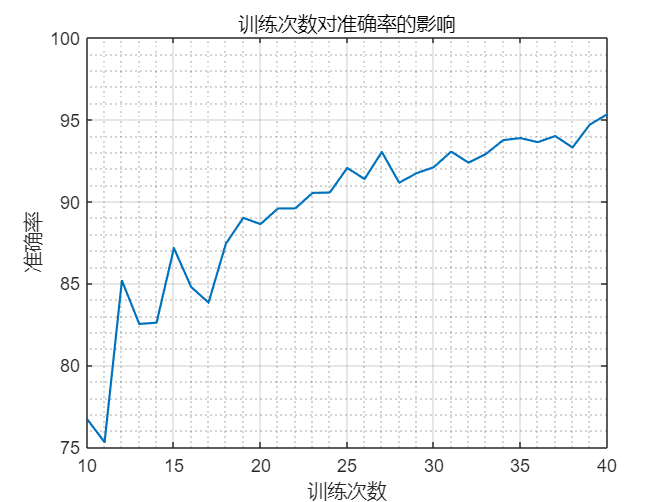



figure();
f1=plot(times_start:step:times_end,acc_times);
set(f1, 'LineWidth', 1.2); % 使用句柄修改线条粗细
title("训练次数对准确率的影响")
xlabel('训练次数')
ylabel('准确率')
grid on;grid minor;